# 105mm榴弹炮弹道仿真与可视化

包含空气阻力的真实弹道模型

clear; clc; close all;

## 1. 火炮参数设置

105mm榴弹炮典型参数（以M101/M102为例）

gun.caliber = 0.105;        % 口径 [m]
gun.muzzle_velocity = 472;  % 初速 [m/s] (高爆弹)
gun.mass = 14.97;           % 弹丸质量 [kg] (M1高爆弹)

## 2. 环境参数

env.g = 9.80665;            % 重力加速度 [m/s^2]
env.rho = 1.225;            % 空气密度 [kg/m^3] (海平面15°C)

## 3. 弹道参数

空气阻力系数 (经验值，炮弹约0.2-0.5)

Cd = 0.35;

% 弹丸截面积 [m^2]
A = pi * (gun.caliber/2)^2;

% 弹道系数 (Ballistic Coefficient)
BC = gun.mass / (Cd * A);   % [kg/m^2]

## 4. 射击条件

elevation_deg = 15;         % 火炮仰角 [度]
elevation_rad = deg2rad(elevation_deg);

## 5. 数值解算 (4阶Runge-Kutta)

状态变量: [x, y, vx, vy]

initial_state = [0; 0;
    gun.muzzle_velocity * cos(elevation_rad);
    gun.muzzle_velocity * sin(elevation_rad)];

% 时间设置
dt = 0.01;                  % 时间步长 [s]
t_max = 30;                 % 最大仿真时间 [s]
t = 0:dt:t_max;
n_steps = length(t);

% 预分配存储
state_history = zeros(4, n_steps);
state_history(:,1) = initial_state;

% RK4积分
for i = 1:n_steps-1
    state_history(:,i+1) = rk4_step(state_history(:,i), dt, @(s) ballistic_ode(s, gun, env, Cd, A));

    % 终止条件: 落地 (y <= 0)
    if state_history(2, i+1) <= 0
        % 线性插值找到精确落地时刻
        y_prev = state_history(2, i);
        y_curr = state_history(2, i+1);
        alpha = y_prev / (y_prev - y_curr);
        state_history(1, i+1) = state_history(1, i) + alpha * (state_history(1, i+1) - state_history(1, i));
        state_history(2, i+1) = 0;
        state_history = state_history(:, 1:i+1);
        t = t(1:i+1);
        break;
    end
end

## 6. 提取结果

x = state_history(1, :);
y = state_history(2, :);
vx = state_history(3, :);
vy = state_history(4, :);
v = sqrt(vx.^2 + vy.^2);

% 弹着点信息
impact_range = x(end);
impact_time = t(end);
impact_velocity = v(end);
impact_angle = atan2(vy(end), vx(end));

## 7. 真空弹道对比 (无空气阻力)

理论抛物线

t_vacuum = linspace(0, impact_time, 500);
x_vacuum = initial_state(3) * t_vacuum;
y_vacuum = initial_state(4) * t_vacuum - 0.5 * env.g * t_vacuum.^2;
% 截断到地面
y_vacuum(y_vacuum < 0) = 0;

## 8. 可视化

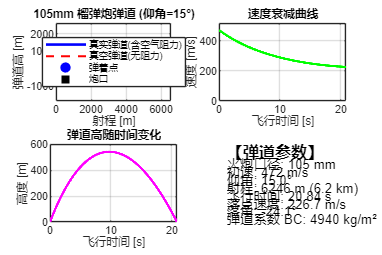

figure('Position', [100, 100, 1200, 800]);

% 子图1: 弹道轨迹
subplot(2,2,1);
plot(x, y, 'b-', 'LineWidth', 2); hold on;
plot(x_vacuum, y_vacuum, 'r--', 'LineWidth', 1.5);
plot(impact_range, 0, 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
plot(0, 0, 'ks', 'MarkerSize', 12, 'MarkerFaceColor', 'k');
xlabel('射程 [m]');
ylabel('弹道高 [m]');
title(sprintf('105mm 榴弹炮弹道 (仰角=%d°)', elevation_deg));
legend('真实弹道(含空气阻力)', '真空弹道(无阻力)', '弹着点', '炮口', 'Location', 'best');
grid on; axis equal;
xlim([0, max(x)*1.05]);

% 子图2: 速度变化
subplot(2,2,2);
plot(t, v, 'g-', 'LineWidth', 2);
xlabel('飞行时间 [s]');
ylabel('速度 [m/s]');
title('速度衰减曲线');
grid on;
xlim([0, impact_time]);
ylim([0, gun.muzzle_velocity * 1.1]);

% 子图3: 高度变化
subplot(2,2,3);
plot(t, y, 'm-', 'LineWidth', 2);
xlabel('飞行时间 [s]');
ylabel('高度 [m]');
title('弹道高随时间变化');
grid on;
xlim([0, impact_time]);

% 子图4: 弹道参数表 (文字显示)
subplot(2,2,4);
axis off;
text(0.1, 0.9, '【弹道参数】', 'FontSize', 12, 'FontWeight', 'bold');
text(0.1, 0.75, sprintf('火炮口径: %.0f mm', gun.caliber*1000));
text(0.1, 0.65, sprintf('初速: %.0f m/s', gun.muzzle_velocity));
text(0.1, 0.55, sprintf('仰角: %.1f°', elevation_deg));
text(0.1, 0.45, sprintf('射程: %.0f m (%.1f km)', impact_range, impact_range/1000));
text(0.1, 0.35, sprintf('飞行时间: %.2f s', impact_time));
text(0.1, 0.25, sprintf('落点速度: %.1f m/s', impact_velocity));
text(0.1, 0.15, sprintf('落角: %.1f°', rad2deg(impact_angle)));
text(0.1, 0.05, sprintf('弹道系数 BC: %.0f kg/m²', BC));

subplot(2,2,4)
xlim([0.04 1.04])
ylim([0.01 1.01])

## 9. 输出控制台报告

fprintf('\n========== 105mm 榴弹炮弹道仿真报告 ==========\n');


========== 105mm 榴弹炮弹道仿真报告 ==========


fprintf('火炮参数:\n');

火炮参数:


fprintf('  口径: %.0f mm\n', gun.caliber*1000);

  口径: 105 mm


fprintf('  初速: %.0f m/s\n', gun.muzzle_velocity);

  初速: 472 m/s


fprintf('  弹重: %.2f kg\n', gun.mass);

  弹重: 14.97 kg


fprintf('\n射击条件:\n');


射击条件:


fprintf('  仰角: %.1f°\n', elevation_deg);

  仰角: 15.0°


fprintf('  空气密度: %.3f kg/m³\n', env.rho);

  空气密度: 1.225 kg/m³


fprintf('\n仿真结果:\n');


仿真结果:


fprintf('  射程: %.0f m (%.2f km)\n', impact_range, impact_range/1000);

  射程: 6246 m (6.25 km)


fprintf('  飞行时间: %.2f s\n', impact_time);

  飞行时间: 20.84 s


fprintf('  最大弹道高: %.0f m\n', max(y));

  最大弹道高: 540 m


fprintf('  落点速度: %.1f m/s (Mach %.2f)\n', impact_velocity, impact_velocity/340);

  落点速度: 226.7 m/s (Mach 0.67)


fprintf('  落角: %.1f°\n', rad2deg(impact_angle));

  落角: -24.1°


fprintf('================================================\n');

## ==================== 局部函数定义 ====================

function dstate = ballistic_ode(state, gun, env, Cd, A)
% 弹道微分方程
% state = [x; y; vx; vy]

x = state(1);
y = state(2);
vx = state(3);
vy = state(4);

% 速度大小
v = sqrt(vx^2 + vy^2);

if v < 0.01
    % 速度太小，阻力忽略
    ax = 0;
    ay = -env.g;
else
    % 空气阻力加速度
    % F_drag = 0.5 * ρ * Cd * A * v^2
    % a_drag = F_drag / m
    drag_acc = 0.5 * env.rho * Cd * A * v^2 / gun.mass;

    % 分解到x、y方向 (阻力与速度方向相反)
    ax = -drag_acc * (vx / v);
    ay = -env.g - drag_acc * (vy / v);
end

dstate = [vx; vy; ax; ay];
end

function next_state = rk4_step(state, dt, f)
% 4阶Runge-Kutta积分器
k1 = f(state);
k2 = f(state + 0.5*dt*k1);
k3 = f(state + 0.5*dt*k2);
k4 = f(state + dt*k3);

next_state = state + dt * (k1 + 2*k2 + 2*k3 + k4) / 6;
end